% initial random network 
Ni = 25;
% rand('twister', sum(100*clock));
rr = triu(rand(Ni),1);
rr = rr+rr';
nn = rr>0.5;

N = 1 * 10^2; % # nodes/steps
M = 5; % # link per step
J = sparse(N,N);

J(1:Ni,1:Ni) = nn;

%  A-B network construction
tic
for ind = Ni+1:N
    K = sum(J);
    Kc = cumsum(K);
    for i_l = 1:M        
        x = floor(rand*sum(K))+1;
        ii = min(find(x<=Kc));
        J(ii,ind) = 1;
        J(ind,ii) = 1;
    end
end
fprintf('ok\n');toc

ok
Elapsed time is 0.006566 seconds.


% 8 s for 10k nodes

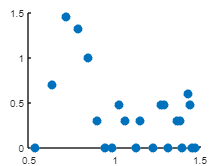

K = sum(J);
clf;
figure; hold on
[Y X] = hist(K,30);
% plot(X,Y,'.')
% plot(log10(X(Y>0 & X<100)),log10(Y(Y>0 & X<100)),'.')
plot(log10(X(Y>0)),log10(Y(Y>0)),'.', 'markersize', 24)

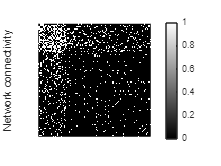

J = full(J);
%cmap = [0 0 1; 1 0 0];
% generate the plot
clf;
imshow(J,'InitialMagnification','fit');
%colormap(cmap);
%clim([-1 1]);
colorbar
ylabel('Network connectivity')

% Initialize the spins
s = ones(N,1);
for i = 1:N
    if rand() < 0.5
       s(i) = 0;
    end
end

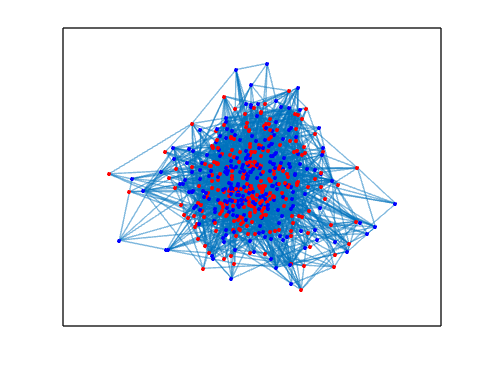

% Visualize the network
% Create graph object
G = graph(J);

% Plot graph and color nodes based on spin values
clf;
h = plot(G);
colormap([1 0 0; 0 0 1]); % Red for -1, blue for 1
node_colors = s + 2; % Map -1 to 1, 1 to 2
h.NodeCData = node_colors;

% Initialize the energy and magnetization
H = 0;
e = zeros(N,1);
for i = 1:N
    e(i) = -0.5 * s(i) * prod(nonzeros(J(:,i).*s(:)));
end
E = sum(e) - H * sum(s);
M = sum(s);

% Set the number of iterations and T points and preallocate arrays to store results
eq_steps = 2 * 10^3;
n_iter = 3* 10 ^3;

% Temperatures to sample
nT = 100;
%Tc = 2 / log(1+sqrt(2)); % Curie temperature
%T = linspace(0, 2*Tc, nT);
T = linspace(0, 30, nT);
E_m = zeros(nT,1);
M_m = zeros(nT,1);

e_avg = zeros(eq_steps, 1);
e_avg(1,1) = E / N;
spins = zeros(N, eq_steps);
spins(:,1) = s(:);

% Equilibration
tic
for t = 1:nT
for step = 2:eq_steps
    % Choose a spin at random and flip it
    r = randi(N);
    if s(r) == 1
       s(r) = 0;
    else
        s(r) = 1;
    end
    
    % Calculate the energy difference
    for i = 1:N
    e(i) = -0.5 * s(i) * prod(nonzeros(J(:,i).*s(:)));
    end
    E = sum(e) - H * sum(s);
    delta_E = E - e_avg(step-1)*N;
    % Calculate new total magnetization
    %M = sum(s);
    
    % Flip the spin with probability exp(-delta_E/kT) or if delta_E < 0
    if delta_E <= 0 || rand() <= exp(-delta_E / T(t))
        spins(:,step) = s(:);
        % Store the energy and magnetization
        e_avg(step) = E / N;
    else
        spins(:,step) = spins(:,step-1);
        s(:) = spins(:,step-1);
        e_avg(step) = e_avg(step-1);
    end
end
end
toc

Elapsed time is 18.451660 seconds.


E_avg = zeros(n_iter, 1);
E_avg(1,1) = e_avg(step);
M_avg = zeros(n_iter, 1);
M_avg(1,1) = mean(spins(:,step));
spin_conf = zeros(N, n_iter);
spin_conf(:,1) = spins(:,step);

tic
for t = 1:nT
for iter = 2:n_iter
    % Choose a spin at random and flip it
    r = randi(N);
    if s(r) == 1
       s(r) = 0;
    else
        s(r) = 1;
    end
    
    % Calculate the energy difference
    for i = 1:N
    e(i) = -0.5 * s(i) * prod(nonzeros(J(:,i).*s(:)));
    end
    E = sum(e) - H * sum(s);
    delta_E = E - E_avg(iter-1)*N;
    % Calculate new total magnetization
    %M = sum(s);
    
    % Flip the spin with probability exp(-delta_E/kT) or if delta_E < 0
    if delta_E <= 0 || rand() <= exp(-delta_E / T(t))
        spin_conf(:,iter) = s(:);
        % Store the energy and magnetization
        E_avg(iter) = E / N;
        M_avg(iter) = mean(s(:));
    else
        spin_conf(:,iter) = spin_conf(:,iter-1);
        s(:) = spin_conf(:,iter-1);
        E_avg(iter) = E_avg(iter-1);
        M_avg(iter) = M_avg(iter-1);
    end
end
E_m(t) = sum(E_avg)/n_iter;
M_m(t) = mean(M_avg(:));
end
toc

Elapsed time is 47.856946 seconds.


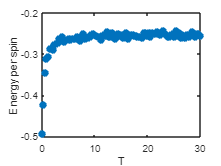

clf;
figure();
plot(T,E_m,'.','MarkerSize',20);
xlabel('T');
ylabel('Energy per spin');

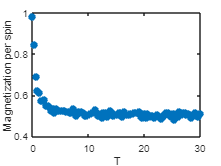


clf;
figure();
plot(T,M_m,'.','MarkerSize',20);
xlabel('T');
ylabel('Magnetization per spin');

% Visualize the spin configuration at time/iteration t
% Plot graph and color nodes based on spin values
clf;
h = plot(G);
colormap([1 0 0; 0 0 1]); % Red for -1, blue for 1
node_colors = spin_conf(:,3000) + 2; % Map -1 to 1, 1 to 2
h.NodeCData = node_colors;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

n_iter = 10000;
nT = 10;
T = linspace(0, 30, nT);
E_m = zeros(nT,1);
M_m = zeros(nT,1);

E_avg = zeros(n_iter, 1);
E_avg(1,1) = E/N;
M_avg = zeros(n_iter, 1);
M_avg(1,1) = mean(s(:));
spin_conf = zeros(N, n_iter);
spin_conf(:,1) = s(:);
H = [10^-2, 10^-1, 1, 10, 10^2];
M_h = zeros(5,nT);

tic
for h = 1:5
for t = 1:nT
for iter = 2:n_iter
    % Choose a spin at random and flip it
    r = randi(N);
    if s(r) == 1
       s(r) = 0;
    else
        s(r) = 1;
    end
    
    % Calculate the energy difference
    for i = 1:N
    e(i) = -0.5 * s(i) * prod(nonzeros(J(:,i).*s(:)));
    end
    E = sum(e) - H(h) * sum(s);
    delta_E = E - E_avg(iter-1)*N;
    % Calculate new total magnetization
    %M = sum(s);
    
    % Flip the spin with probability exp(-delta_E/kT) or if delta_E < 0
    if delta_E <= 0 || rand() <= exp(-delta_E / T(t))
        spin_conf(:,iter) = s(:);
        % Store the energy and magnetization
        E_avg(iter) = E / N;
        M_avg(iter) = mean(s(:));
    else
        spin_conf(:,iter) = spin_conf(:,iter-1);
        s(:) = spin_conf(:,iter-1);
        E_avg(iter) = E_avg(iter-1);
        M_avg(iter) = M_avg(iter-1);
    end
end
M_m(t) = mean(M_avg(:));
end
M_h(h,:) = M_m(:);
end
toc

Elapsed time is 160.191635 seconds.


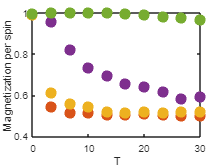

clf;
figure();
plot(T,M_h(1,:),'.','MarkerSize',10,'MarkerFaceColor','r');
hold on
plot(T,M_h(2,:),'.','MarkerSize',30,'MarkerFaceColor','g');
plot(T,M_h(3,:),'.','MarkerSize',30,'MarkerFaceColor','b');
plot(T,M_h(4,:),'.','MarkerSize',30,'MarkerFaceColor','c');
plot(T,M_h(5,:),'.','MarkerSize',30,'MarkerFaceColor','m');
xlabel('T');
ylabel('Magnetization per spin');